%% Sample script to generate trajectory data for the lab robot
%
% Generates a sample trajectory for the three robot axes and saves it as
% binary files that can be transfered to the PLC and read as a trajectory.
%
% Maximilian Herrmann
% Chair of Automatic Control
% TUM School of Engineering and Design
% Technical University of Munich

% Preparation
clear
close all


%% Script settings

% File name up to the counter digits
% Corresponds to TrajReaderParams.FileName in the PLC reading program
trajFileBaseName = 'Trajectory_'; 

% File Ending after the counter digits
% Corresponds to TrajReaderParams.FileEnding in the PLC reading program
trajFileEnding   = '.bin';     

% File path, where the files will be saved (with '/' at the end) 
fileDir = 'for_experiments/generatedTrajData/'; 

inputFile = 'identification_trajectories/traj/kinError/traj_kinError_axis1.mat';
inputTraj = load(inputFile);

% Sample time, at which the trajectory will be read
% ( i.e., task class cycle time of the PLC rading program)
tSample = inputTraj.time(2) - inputTraj.time(1)

tSample = 0.0100



%% Generate Trajectory Data
% As an example: Some simple sine waves with phase shift

%tVec = inputTraj.time; % End time / length of the trajectory (s)
tVec = (tSample:tSample:size(inputTraj.theta,1)*tSample)';
nSamples = length(tVec);

x = inputTraj.theta(1:end,:);

fprintf('Length of generated trajectory: %d samples\n', nSamples)

Length of generated trajectory: 9038 samples


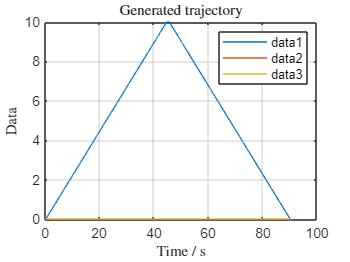


%% Save as binary data

% Create output folder if it doesn't exist
if ~isfolder(fileDir) && ~isempty(fileDir)
    mkdir(fileDir);
end

% Save data as 32-Bit Single binary files
for iVar = 1:size(x, 2)

    fileName = sprintf('%s/%s%d%s', fileDir, trajFileBaseName, iVar-1, trajFileEnding);

    fileID = fopen(fileName, 'w');
    fwrite(fileID, x(:,iVar), 'single');
    fclose(fileID);
end


%% Plot generated trajectories

figure;
plot(tVec, x);
legend;
grid on;
title('Generated trajectory', 'Interpreter', 'latex')
xlabel('Time / s', 'Interpreter', 'latex')
ylabel('Data', 'Interpreter', 'latex')

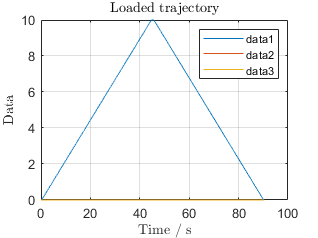



%% Read back binary data for verification

for iVar = 1:size(x, 2)

    fileName = sprintf('%s/%s%d%s', fileDir, trajFileBaseName, iVar-1, trajFileEnding);

    fileID = fopen(fileName, 'r');
    xBin(:,iVar) = fread(fileID, '*single');
    fclose(fileID);
end

% Plot verification data
figure;
plot(tVec, xBin);
legend;
grid on;
title('Loaded trajectory', 'Interpreter', 'latex')
xlabel('Time / s', 'Interpreter', 'latex')
ylabel('Data', 'Interpreter', 'latex')